# Q1

clear all
syms k integer
assumeAlso(k>=0)
syms a b n
assume(a ~= b)
x(k) = a^k;
h(k) = b^k;

## 直接法

y1(k) = symsum(h(n)*x(k-n), n, [0, k])

$$y1(k) = \frac{a\,a^{k}-b\,b^{k}}{a-b}$$

## Z变换法

syms z
assumeAlso([a>0, b>0, k>0])
y2(k) = iztrans(ztrans(h, k, z)*ztrans(x, k, z), z, k)

$$y2(k) = \frac{a\,a^{k}}{a-b}-\frac{b\,b^{k}}{a-b}$$

# Q2

clear all
syms f(t) s
Df = diff(f, t);
LDf = laplace(Df, t, s)

$$LDf = s\,\mathrm{laplace}\left(f\left(t\right),t,s\right)-f\left(0\right)$$

# Q3

clear all
syms x y
eq = x^2+y^2 == 1;
cond = x*y == 2;
s = solve(eq, cond);
disp([s.x, s.y])

$$\begin{array}{l} \left(\begin{array}{cc} -\frac{\sigma_{1}}{2}+\sigma_{3} & -\sigma_{1}\\ -\frac{\sigma_{2}}{2}+\sigma_{4} & -\sigma_{2}\\ \frac{\sigma_{1}}{2}-\sigma_{3} & \sigma_{1}\\ \frac{\sigma_{2}}{2}-\sigma_{4} & \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\frac{1}{2}-\frac{\sqrt{15}\,\mathrm{i}}{2}}\\ \sigma_{2}=\sqrt{\frac{1}{2}+\frac{\sqrt{15}\,\mathrm{i}}{2}}\\ \sigma_{3}=\frac{{\left(\frac{1}{2}-\frac{\sqrt{15}\,\mathrm{i}}{2}\right)}^{3/2}}{2}\\ \sigma_{4}=\frac{{\left(\frac{1}{2}+\frac{\sqrt{15}\,\mathrm{i}}{2}\right)}^{3/2}}{2} \end{array}$$

# Q4

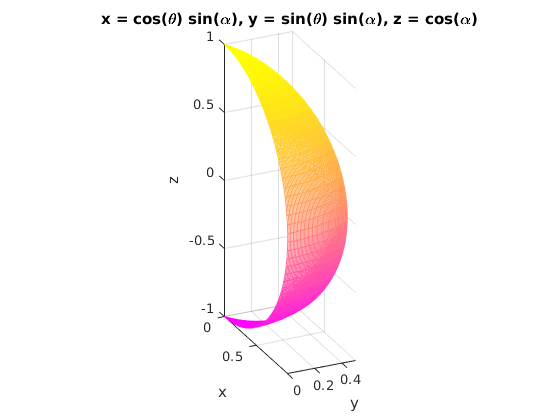

clear all
syms alpha theta
x = 'cos(theta)*sin(alpha)';
y = 'sin(theta)*sin(alpha)';
z = 'cos(alpha)';
ezmesh(x, y, z, [0, pi, 0, pi/6])
xlabel('x'), ylabel('y'), zlabel('z')
colormap('spring')
axis equal
view([65, 25])

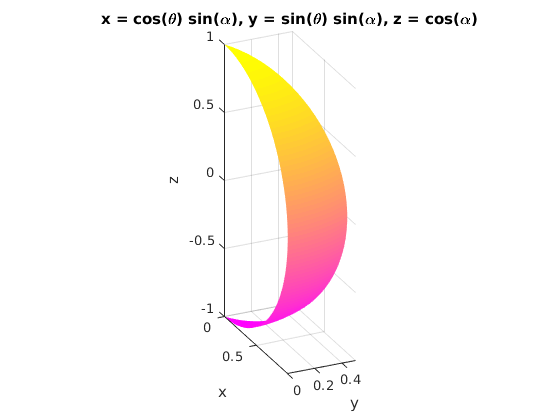

ezsurf(x, y, z, [0, pi, 0, pi/6])
shading interp
axis equal
view([65, 25])

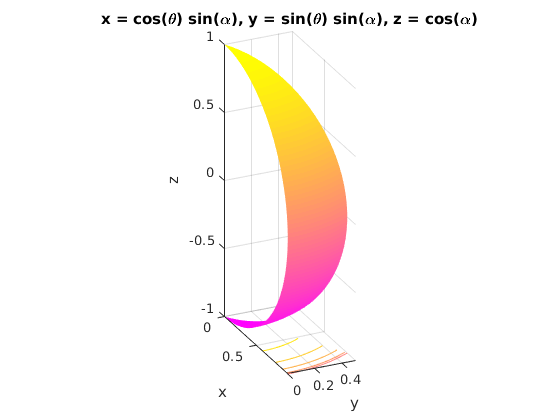

ezsurfc(x, y, z, [0, pi, 0, pi/6])
shading interp
axis equal
view([65, 25])

# Q5

## (1)

### (a)

$xy-z=0$ 的二次项部分的矩阵为$\left\lbrack \begin{array}{ccc}
0 & \frac{1}{2} & 0\\
\frac{\;1}{2} & 0 & 0\\
0 & 0 & 0
\end{array}\right\rbrack$，

正交特征向量组为$\left\lbrack \begin{array}{ccc}
\frac{\;\sqrt{\;2}}{2} & \frac{\;\sqrt{\;2}}{2} & 0\\
\frac{\;\sqrt{\;2}}{2} & -\frac{\;\sqrt{\;2}}{2} & 0\\
0 & 0 & 1
\end{array}\right\rbrack$，

作对应的坐标变换之后得

$\frac{{x'}^2}{2}-\frac{{y'}^2}{2}-z' = 0$，

是双曲抛物面方程

### (b)

$x^2-2xy+2y+z^2-4=0$的二次项部分的矩阵为$\left\lbrack \begin{array}{ccc}
1 & -1 & 0\\
-1 & 0 & 0\\
0 & 0 & 0
\end{array}\right\rbrack$，

特征向量组为$\left\lbrack \begin{array}{ccc}
1 & \frac{\;1-\sqrt{\;5}}{2} & 0\\
\frac{\;\sqrt{\;5}-1}{2} & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$，

作对应的坐标变换之后得


$$\sqrt{5}{x'}^2+\frac{5-3\sqrt{5}}{2}{y'}^2+(1-\sqrt{5})x'+2y'+{z'}^2-4=0$$


再做平移 $x''=x'+\frac{1-\sqrt{5}}{2\sqrt{5}}$，$y'' = y'+\frac{2}{5-3\sqrt{5}}$ 后得


$$\sqrt{5}{x''}^2+\frac{5-3\sqrt{5}}{2}{y''}^2+{z''}^2-3=0$$


是单叶双曲面方程

## (2)(3)

syms x y z

1) 平面


$$x^2-2y^2=0, \quad z\in R$$


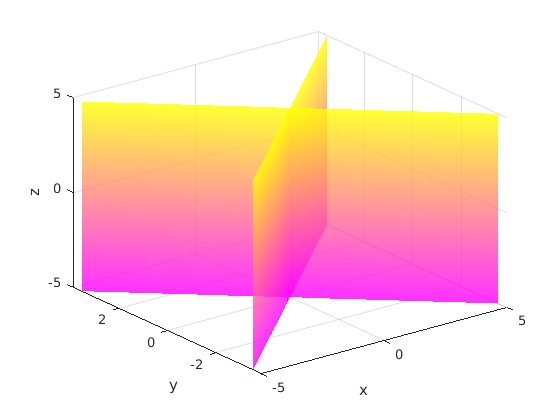

f1 = x^2 - 2*y^2;
fimplicit3(f1,'EdgeColor','none','FaceAlpha',.8)
xlabel('x'), ylabel('y'), zlabel('z')

2) 柱面


$$x^2+2y^2 - 3=0, \quad z\in R$$


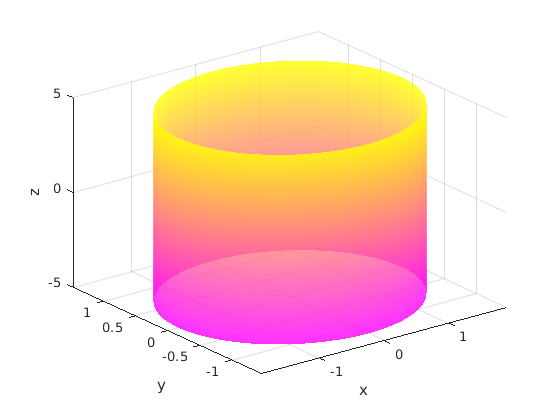

f2 = x^2 + 2*y^2 - 3;
fimplicit3(f2,'EdgeColor','none','FaceAlpha',.8)
xlabel('x'), ylabel('y'), zlabel('z')

3) 锥面


$$x^2+2y^2-z^2 = 0$$


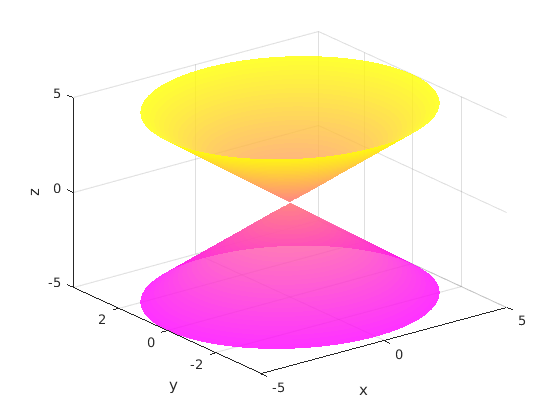

f3 = x^2 +2*y^2 - z^2;
fimplicit3(f3,'EdgeColor','none','FaceAlpha',.8)
xlabel('x'), ylabel('y'), zlabel('z')

4) 椭球面


$$x^2+2y^2+3z^2 -4 = 0$$


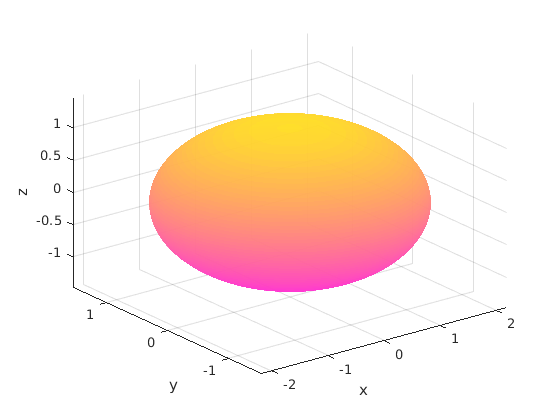

f4 = x^2 + 2*y^2 + 3*z^2 - 4;
fimplicit3(f4,'EdgeColor','none','FaceAlpha',.8)
xlabel('x'), ylabel('y'), zlabel('z')

5) 单叶双曲面

Q5(1)(b): $x^2-2xy+2y+z^2-4=0$

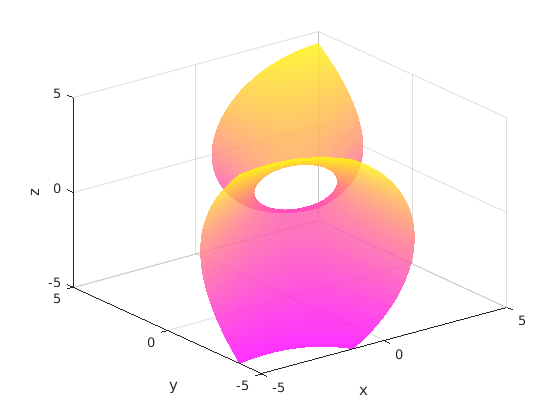

f5 = x^2 - 2*x*y + 2*y + z^2 - 4;
fimplicit3(f5,'EdgeColor','none','FaceAlpha',.8)
xlabel('x'), ylabel('y'), zlabel('z')

6) 双叶双曲面


$$x^2-2xy+2y+z^2+4=0$$


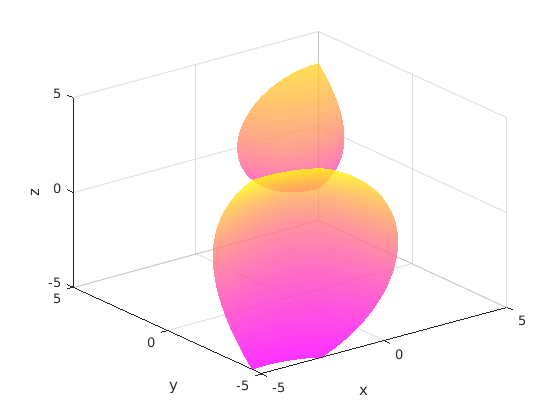

f6 = x^2 - 2*x*y + 2*y + z^2 + 4;
fimplicit3(f6,'EdgeColor','none','FaceAlpha',.8)
xlabel('x'), ylabel('y'), zlabel('z')

6) 椭圆抛物面


$$x^2+2y^2-3z=0$$


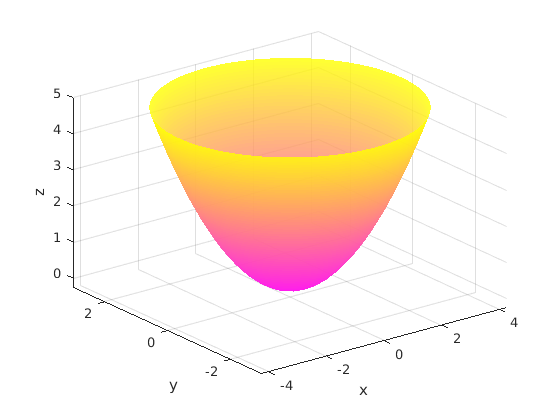

f7 = x^2 + 2*y^2 - 3*z;
fimplicit3(f7,'EdgeColor','none','FaceAlpha',.8)
xlabel('x'), ylabel('y'), zlabel('z')

7) 双曲抛物面

Q5(1)(a): $xy-z=0$

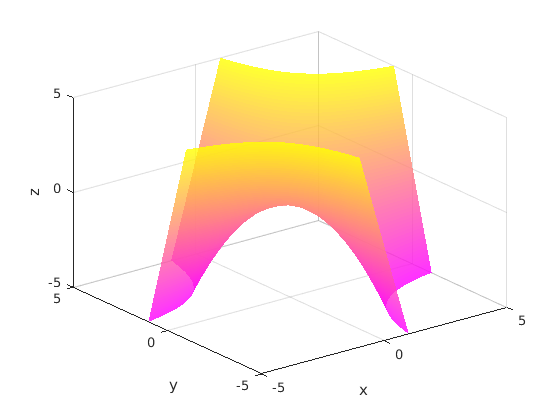

f8 = x*y - z;
fimplicit3(f8,'EdgeColor','none','FaceAlpha',.8)
xlabel('x'), ylabel('y'), zlabel('z')